%% 1. Definição do Sistema (Espaço de Estados)
num = 0.8333;
den = [1 0.4167 0];
G = tf(num, den);

% Convertendo e garantindo os tamanhos corretos das matrizes
sys = ss(G);
A = sys.A;
B = sys.B;
C = sys.C(1, :); % Força C a ser um vetor linha 1x2
D = 0;           % Como o drone não tem transmissão direta, D é um escalar (0)

disp('Matriz A:'), disp(A)

Matriz A:
   -0.4167         0
    0.5000         0



disp('Matriz B:'), disp(B)

Matriz B:
     1
     0



disp('Matriz C:'), disp(C)

Matriz C:
         0    1.6666



disp('Matriz D:'), disp(D)

Matriz D:
     0




%% 2. Verificação de Controlabilidade
Co = ctrb(A, B);
posto = rank(Co);

fprintf('O posto da matriz de controlabilidade é: %d\n', posto);

O posto da matriz de controlabilidade é: 2


if posto == size(A,1)
    disp('O sistema é totalmente controlável! (Posto Cheio)');
else
    disp('Atenção: O sistema NÃO é controlável.');
end

O sistema é totalmente controlável! (Posto Cheio)



%% 3. Projeto do Controlador LQR
Q = [10 0; 
     0  1]; 
R = 0.1;    

K = lqr(A, B, Q, R);
disp('Ganho K calculado:'), disp(K)

Ganho K calculado:
    9.7487    3.1623



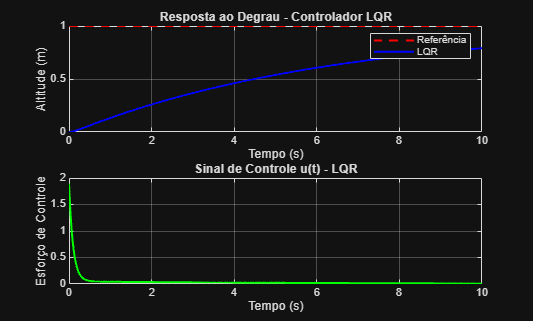


%% 4. Simulação em Malha Fechada
% 1. Ajuste do ganho pré-filtro kr para rastreamento perfeito (Garante que o drone chegue em 1m)
% kr = -1 / (C * inv(A - B*K) * B) 
% Usando a divisão da barra invertida do MATLAB (\) que é computacionalmente mais segura e resolve o problema:
kr = -1 / (C * ((A - B*K) \ B));

% 2. Definição das matrizes do sistema em malha fechada
A_cl = A - B*K;
B_cl = B * kr;
C_cl = C;
D_cl = D;

sys_cl = ss(A_cl, B_cl, C_cl, D_cl);

% 3. Tempo de simulação (Igual ao do PID)
t = 0:0.01:10;
r = ones(size(t)); % Referência: subir 1 metro

% 4. Simulação da resposta do drone (Altitude)
[y_lqr, t, x] = step(sys_cl, t);

% 5. Cálculo do sinal de controle u(t) = kr*r - K*x'
% Ajustando as dimensões para que a multiplicação case perfeitamente
u_lqr = kr * r - (K * x');

%% 5. Plot dos Gráficos
figure;
subplot(2,1,1);
plot(t, r, 'r--', t, y_lqr, 'b', 'LineWidth', 1.5);
title('Resposta ao Degrau - Controlador LQR');
xlabel('Tempo (s)'); ylabel('Altitude (m)');
legend('Referência', 'LQR'); grid on;

subplot(2,1,2);
plot(t, u_lqr, 'g', 'LineWidth', 1.5);
title('Sinal de Controle u(t) - LQR');
xlabel('Tempo (s)'); ylabel('Esforço de Controle');
grid on;


%% 6. Cálculo das Métricas de Desempenho (Para a sua Tabela!)
erro = r' - y_lqr; 
dt = 0.01;         

RMSE = sqrt(mean(erro.^2));
ISE  = sum(erro.^2) * dt;
IAE  = sum(abs(erro)) * dt;
ITAE = sum(t' .* abs(erro)) * dt;

fprintf('\nMétricas de Desempenho do LQR:\n');


Métricas de Desempenho do LQR:


fprintf('RMSE: %.4f\n', RMSE);

RMSE: 0.5592


fprintf('ISE:  %.4f\n', ISE);

ISE:  3.1304


fprintf('IAE:  %.4f\n', IAE);

IAE:  5.1106


fprintf('ITAE: %.4f\n', ITAE);

ITAE: 0.0000
ITAE: 0.0511
ITAE: 0.1022
ITAE: 0.1533
ITAE: 0.2044
ITAE: 0.2555
ITAE: 0.3066
ITAE: 0.3577
ITAE: 0.4088
ITAE: 0.4600
ITAE: 0.5111
ITAE: 0.5622
ITAE: 0.6133
ITAE: 0.6644
ITAE: 0.7155
ITAE: 0.7666
ITAE: 0.8177
ITAE: 0.8688
ITAE: 0.9199
ITAE: 0.9710
ITAE: 1.0221
ITAE: 1.0732
ITAE: 1.1243
ITAE: 1.1754
ITAE: 1.2265
ITAE: 1.2776
ITAE: 1.3288
ITAE: 1.3799
ITAE: 1.4310
ITAE: 1.4821
ITAE: 1.5332
ITAE: 1.5843
ITAE: 1.6354
ITAE: 1.6865
ITAE: 1.7376
ITAE: 1.7887
ITAE: 1.8398
ITAE: 1.8909
ITAE: 1.9420
ITAE: 1.9931
ITAE: 2.0442
ITAE: 2.0953
ITAE: 2.1465
ITAE: 2.1976
ITAE: 2.2487
ITAE: 2.2998
ITAE: 2.3509
ITAE: 2.4020
ITAE: 2.4531
ITAE: 2.5042
ITAE: 2.5553
ITAE: 2.6064
ITAE: 2.6575
ITAE: 2.7086
ITAE: 2.7597
ITAE: 2.8108
ITAE: 2.8619
ITAE: 2.9130
ITAE: 2.9641
ITAE: 3.0153
ITAE: 3.0664
ITAE: 3.1175
ITAE: 3.1686
ITAE: 3.2197
ITAE: 3.2708
ITAE: 3.3219
ITAE: 3.3730
ITAE: 3.4241
ITAE: 3.4752
ITAE: 3.5263
ITAE: 3.5774
ITAE: 3.6285
ITAE: 3.6796
ITAE: 3.7307
ITAE: 3.7818
ITAE: 3.8329
ITAE: 3.8841